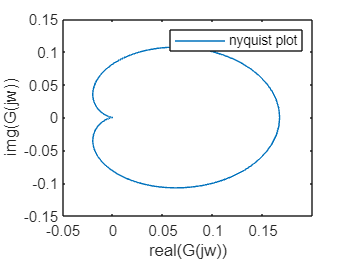

%Defining transfer function
num = [1,1];
den = [1,6,11,6];

lim = 1000;
d = 0.1;
len = (2*lim/d)+1;
wr = linspace(-lim,lim,len);
Grl = zeros(size(wr)); % Real part of G(jw)
Gimag = zeros(size(wr)); % Imag part of G(jw)
Gimag_popov = zeros(size(wr)); % w*Imag(G(jw))
iter = 1;
w_zero_x = 0;
w_iter = 0;


img = 1i;

if size(num,2)>= size(den,2)
    disp("G(s) is not strictly proper!!");

else
    Gs = tf(num,den);
    for w = -lim:d:lim
        Grl(iter) = real(evalfr(Gs,w*img));
        Gimag(iter) = imag(evalfr(Gs,w*img));
        % To identify the point of x-intercept
        if iter>1
        if Gimag(iter)*Gimag(iter-1)<=0
            w_zero_x = Grl(iter);
            w_iter = iter;
        end
        end
        iter = iter+1;
    end   
    Gimag_popov = wr.*Gimag;                                
%     k = -(1/w_zero_x)  % Sector limit(Based on intercept of curve)
%     %Slope of limit line
%     slope = ((Gimag(w_iter)*wr(w_iter))-(Gimag(w_iter-1)*wr(w_iter-1)))/(Grl(w_iter)-Grl(w_iter-1))
%     x_line = -0.05:0.01:0.05;
%     y_line = slope*(x_line-(-1/k));
%     plot(Grl,Gimag_popov,x_line,y_line);
%     xlabel("real(G(jw))");
%     ylabel("w*img(G(jw))");
%     legend('Popov plot','Limit line')

   plot(Grl,Gimag);
   xlabel("real(G(jw))");
   ylabel("img(G(jw))");
   legend('nyquist plot')

end